# ECG data acquisiton, visualization and analysis with the Heart & Brain Spiker Box

In this live-script, you are going to learn how to:

- Acquire ECG datasets with the [Heart & Brain Spiker Box](https://backyardbrains.com/products/heartandbrainspikershieldbundle) in MATLAB & Simulink

- Pre-process ECG datasets

- Visualize ECG datasets

- Analyze ECG datasets

For some background information on ECGs, please refer to the [Backyard Brains documentation](https://backyardbrains.com/experiments/heartrate)

# Installation

- Connect your Heart & Brain Spiker Box via USB

- [Install Arduino Support Package for MATLAB](https://de.mathworks.com/matlabcentral/fileexchange/47522-matlab-support-package-for-arduino-hardware)

- [Install Arduino Support Package for Simulink](https://www.mathworks.com/matlabcentral/fileexchange/40312-simulink-support-package-for-arduino-hardware)

- Attach the electrodes as demonstrated by Backyard Brains in [this video](https://youtu.be/seWZmwg7h7U)

# Connection

Go to your Device Manager and identify the COM port

a = arduino('COM5','Uno');

# Getting started with Arduino

Let's test whether the connection is working.

In this example we use the piezo speaker of the Arduino. The playTone() function allows us to easily transmit frequencies of different durations.

freq =1500;
dur = 1;
playTone(a,'D9',freq,dur);

Let's listen to some real stuff

addpath("auxilliary\")
playGOT(a,dur);

We can also play around with the different LEDs

  
writeDigitalPin(a,'D5',1)
brightness = 3;
writePWMVoltage(a,'D5',brightness);

 
writeDigitalPin(a,'D5',0)

# Read & plot signal "live"

Let's now read the analog signals from the ECG electrodes. the readVoltage() function reads the Voltage from an analog signal. We can then create a live plot from the signals we've measured. We can set the (pseudo-) sample time via the pause function, if we want to stream data with a pre-set, more precise sampling time we better use Simulink. We will look at how to stream data to Simulink afterwards

## Read analog example signal from Arduino

A1  = readVoltage(a,"A0");

## Set parameters

sampleTime = 1/250; %250 Hz
time = linspace(0,30,30/sampleTime)'; %create evenly spaced time vector between 0 and 30 seconds
data = zeros*linspace(0,30,30/sampleTime)'; %create evenly spaced data vector between 0 and 30 seconds
count = 0;

## "Live"- stream data to MATLAB

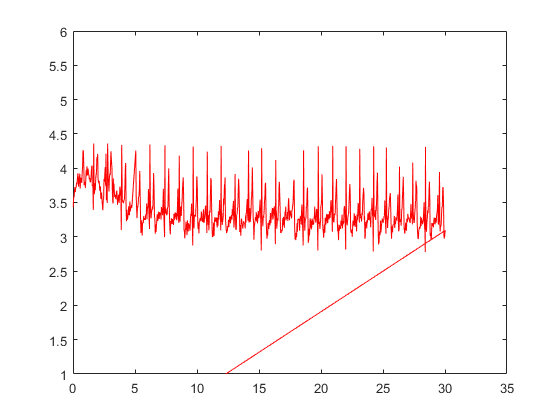

plotGraph = plot(time,data,'-r' );
ylim([1 6])
tic
while ishandle(plotGraph) && ~any(time>30)
    dat = readVoltage(a,"A0");
    count = count + 1;
    time(count) = toc;
    data(count) = dat;
    set(plotGraph,'XData',time,'YData',data);
    pause(sampleTime);
end

# Record signal in Simulink

We can stream data to Simulink with a preconfigured sampleTime in our model. This allows us to record more accurate data. Let's open our Simulink model and start recording

clear a
RecordECG
codertarget.arduinobase.registry.setBaudRate(gcs,115200);

Baud rate has been set to 115200


## Setup Heart & Brain Spiker Box for Simulink

- go to the Hardware tab of the model

- click on "Hardware Settings"

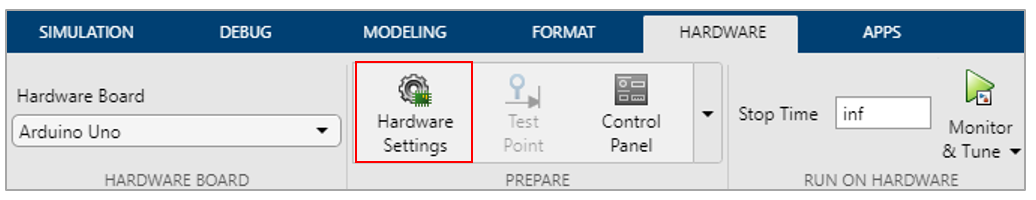

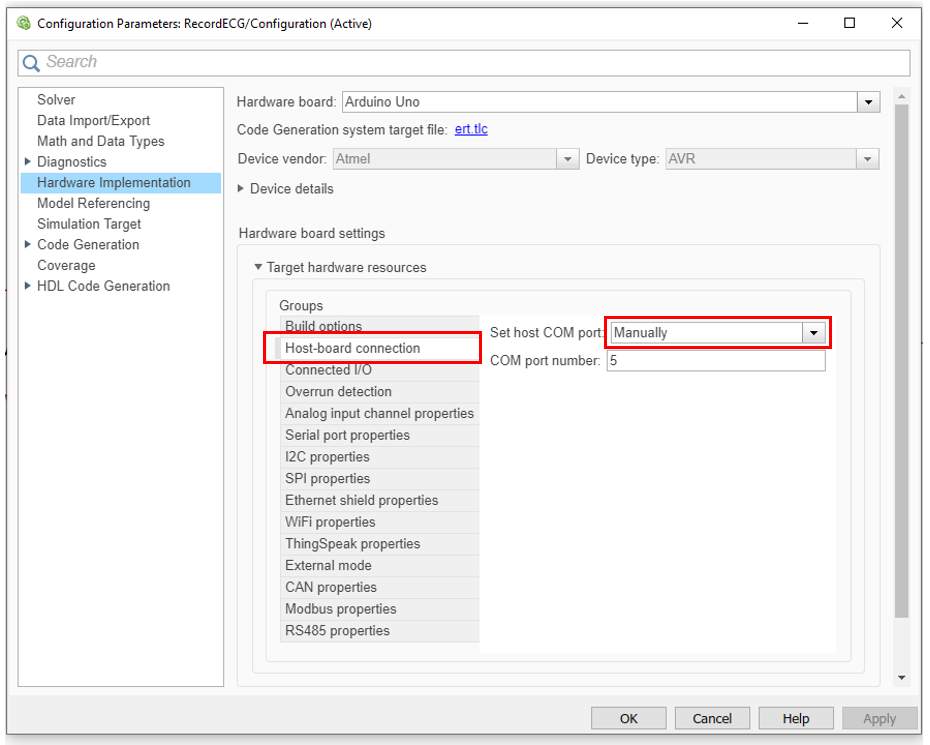

- set host COM port manually

- if you don't know the COM port number go to your device manager (just type device manager in your search bar on windows)

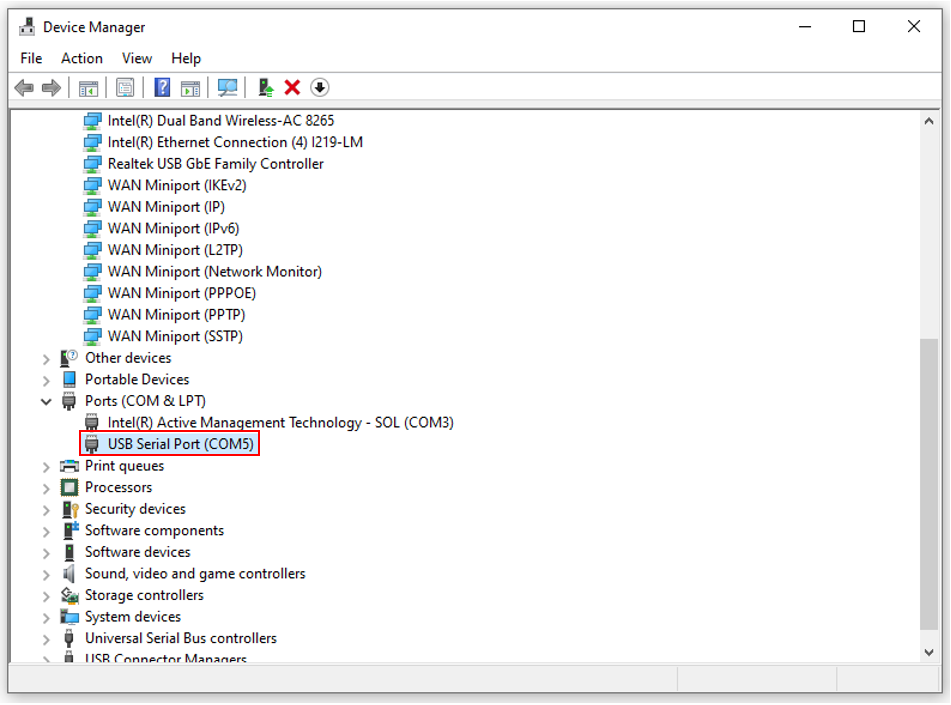

## Start recording

We are going to record our signals in the "external mode" in Simulink.

It basically means that we run our model on hardware while visualizing data in Simulink.

- In the Hardware tab of your model click the "Monitor & Tune" button

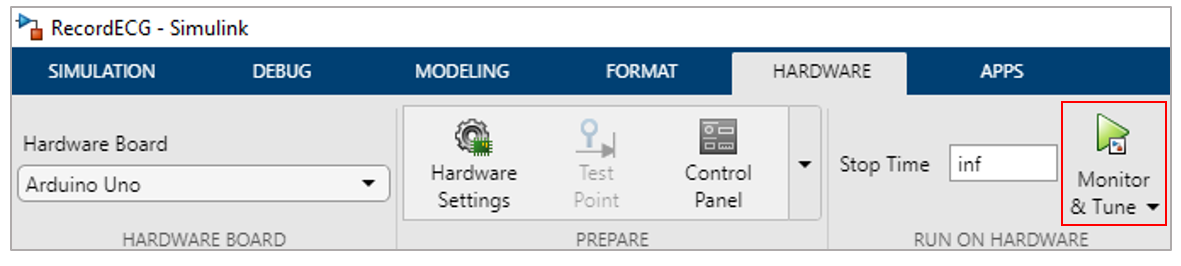

- restart the Heart & Brain Spiker box by switching it on and off 

- click on "connect"

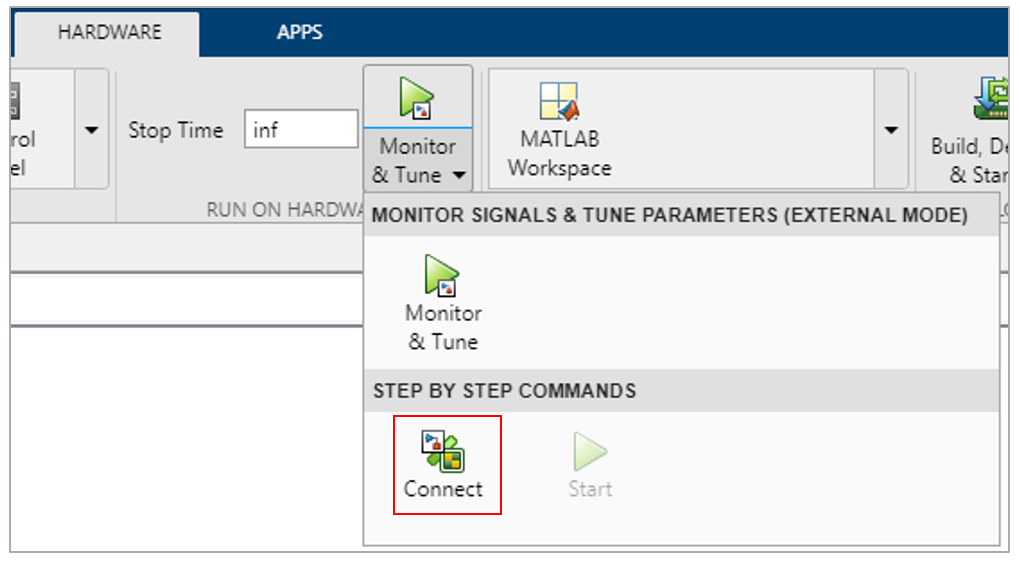

- after a couple of seconds you should see the "Start" icon, click it

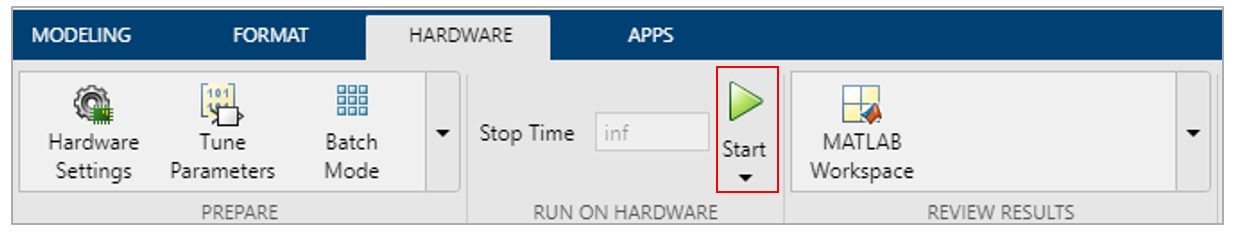

- by clicking the "Start" button, you start recording your signal, you can visualize it by double clicking on the Scope block

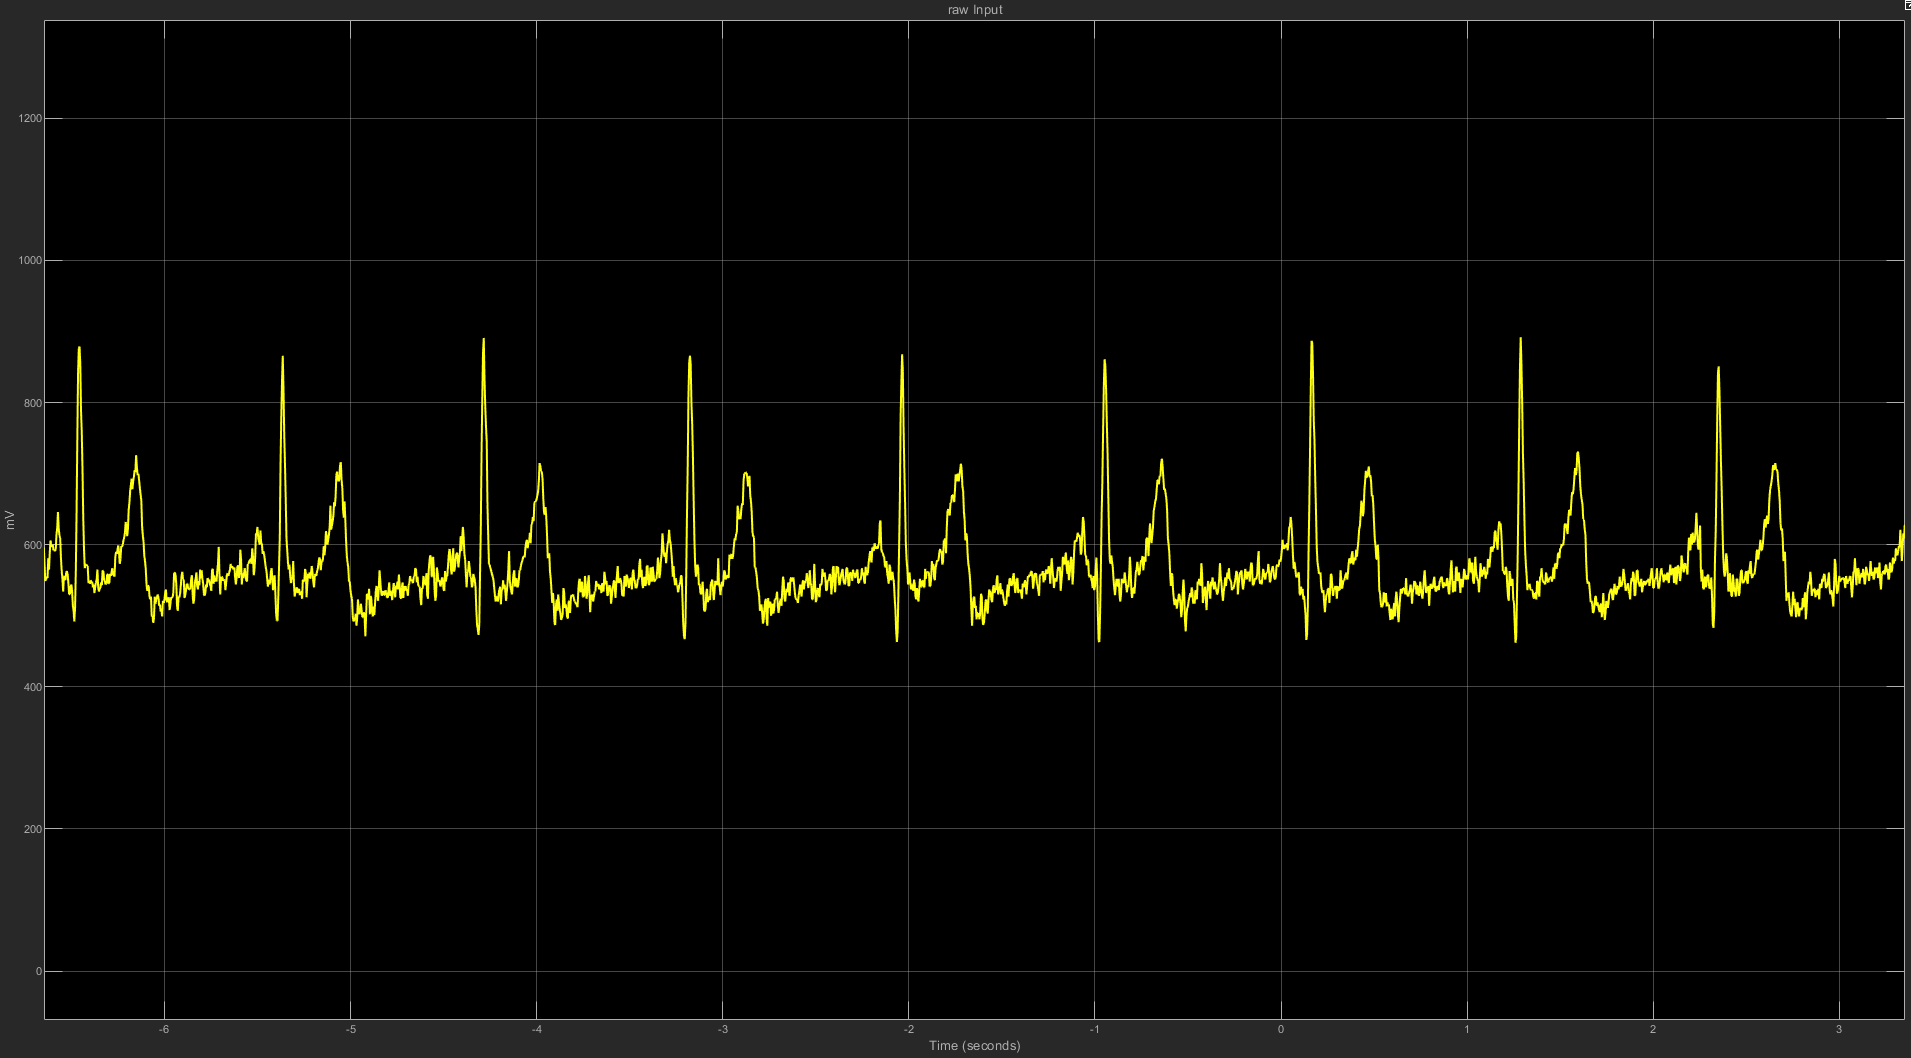

## Process recorded data in MATLAB

We've logged our data to a variable "ECGdata", which we can now access in our base-workspace in MATLAB

addpath("RecordedData\")
if exist('ECGdata','var')
t = ECGdata.time;
signalRaw = double(squeeze(ECGdata.signals.values));
else
    load RawSignal.mat %use example recording if you haven't recorded any data
end
signalRaw = signalRaw*0.00127156576; %multiply ADC units with calibration coefficient to get mV

### Visualize the recording

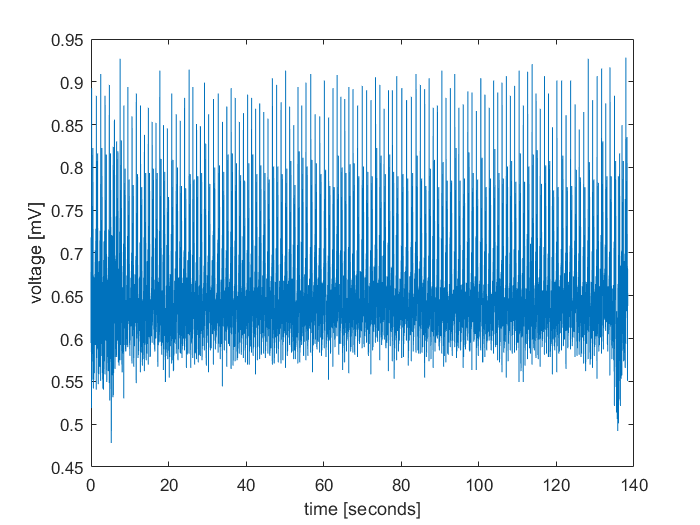

plot(t,signalRaw)
xlabel('time [seconds]');
ylabel('voltage [mV]');

### Clean-up recorded data

Apparently we have some artefacts in our data that were caused by attaching the electrodes and/or moving, let's get rid of them with simple indexing:

let's cut 10 seconds from the beginning

startIdx = find(round(t,4)==10);

let's cut the data after 120 seconds

endIdx = find(round(t,4)==120);
t = t(startIdx:endIdx);
signalRaw = signalRaw(startIdx:endIdx);

#### Visualize the cleaned up result

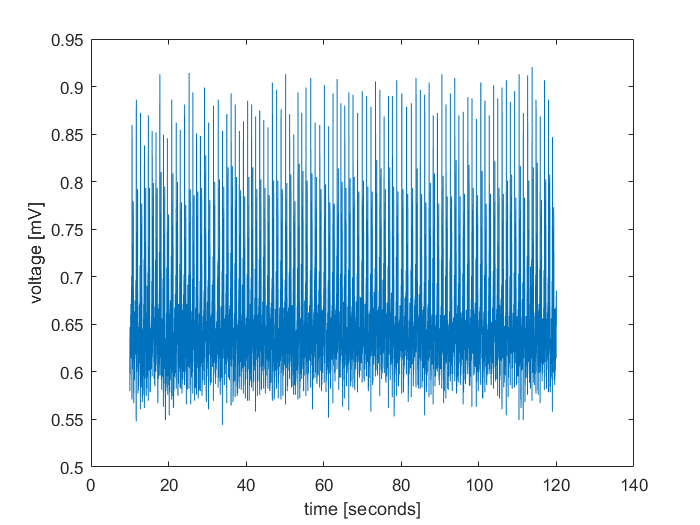

plot(t,signalRaw)
xlabel('time [seconds]');
ylabel('voltage [mV]');

We now have a nice signal recording. Let's now quickly adjust the time-axis to make it more readable

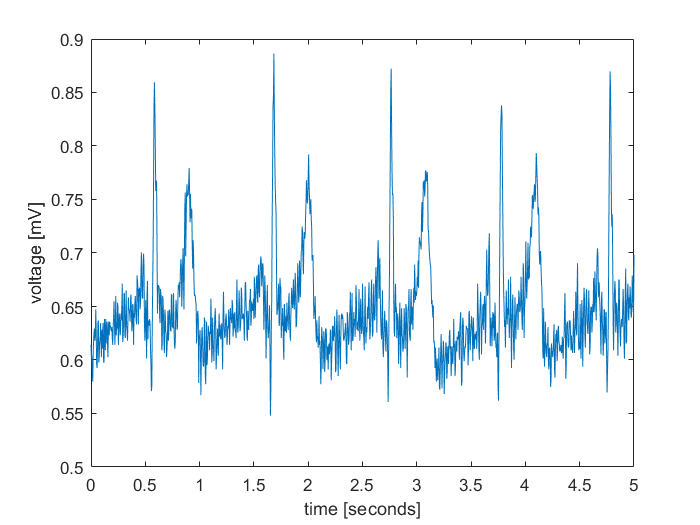

t = t-t(1);
plot(t,signalRaw)
xlabel('time [seconds]');
ylabel('voltage [mV]');
xlim([0 5])

### Detrend the data

If we notice a voltage trend in our data that is probably not caused by real signals, let's use the remove trends live task to detrend our data. This task will also make our relative signal more readable

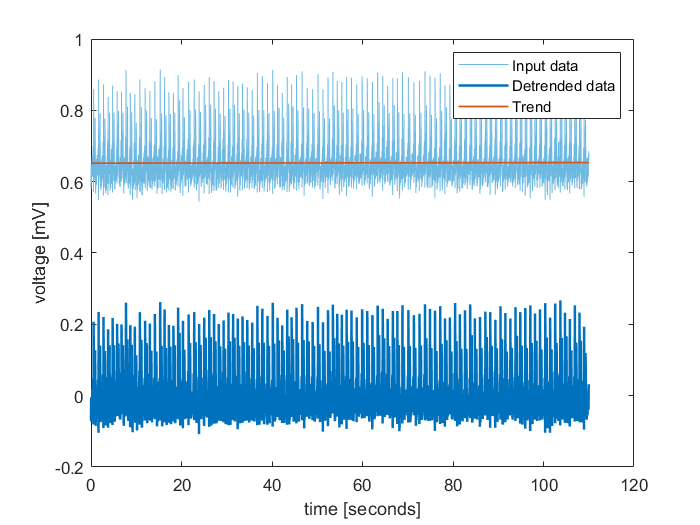

% Remove trend from data
detrendedData = detrend(signalRaw,'SamplePoints',t);

% Display results
clf
plot(t,signalRaw,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(t,detrendedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(t,signalRaw-detrendedData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend
xlabel('time [seconds]');
ylabel('voltage [mV]');

### About data filtering & smoothing

Smoothing is how we discover important patterns in our data while leaving out things that are unimportant (i.e. noise). We use filtering to perform this smoothing. The goal of smoothing is to produce slow changes in value so that it's easier to see trends in our data.

There are many different [filtering](https://www.mathworks.com/help/dsp/filter-design-and-analysis.html) and [smoothing](https://www.mathworks.com/help/curvefit/smoothing-data.html) methods available in MATLAB.

Here is an overview of basic, commonly used filters:

    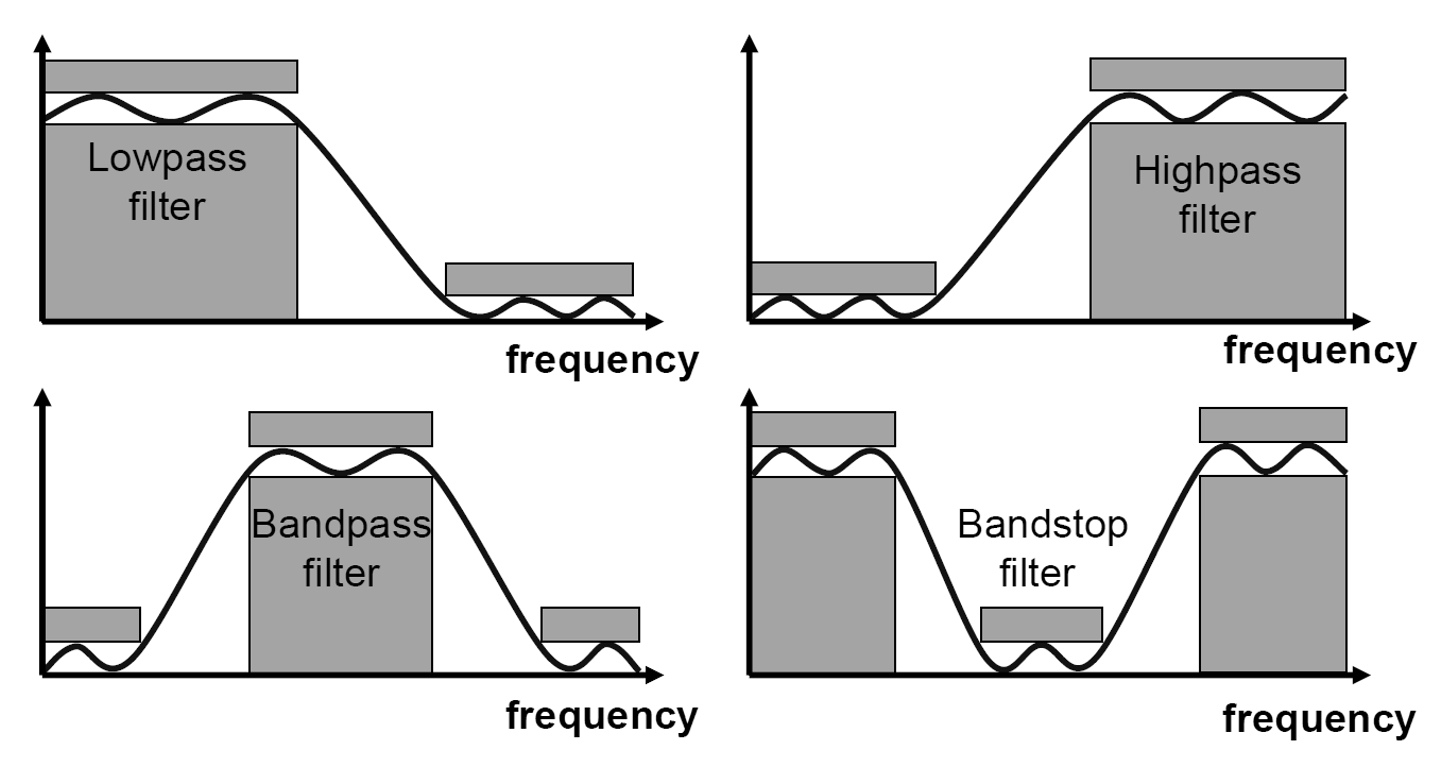

In this example let's look at a moving mean filter:

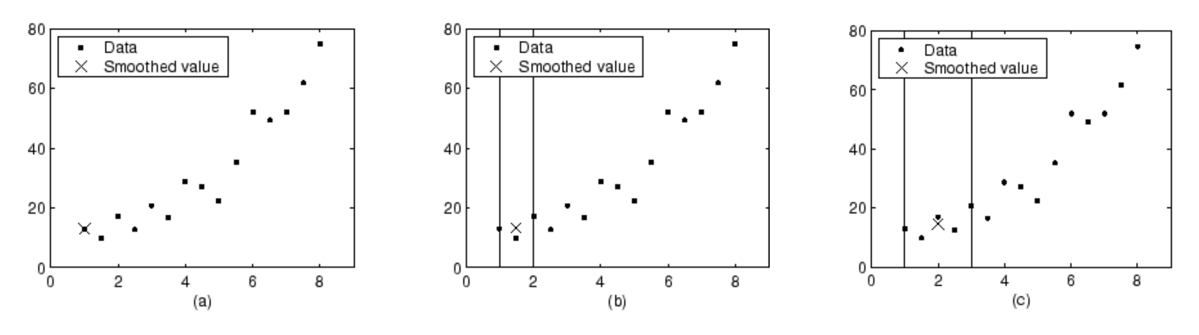

### Smooth data

By using a live-task to smooth your data, you can play around with the paramaters and try out different smoothing parameters.

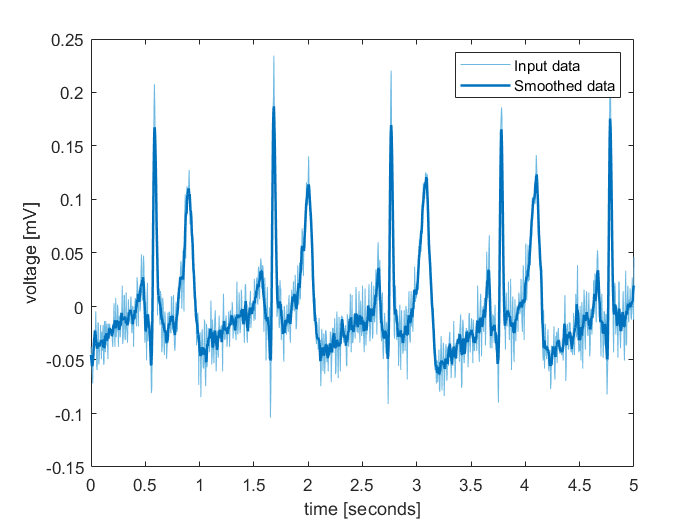

% Smooth input data
smoothedData = smoothdata(detrendedData,'movmean',0.02,'SamplePoints',t);

% Display results
clf
plot(t,detrendedData,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(t,smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend
xlim([0 5])
xlabel('time [seconds]');
ylabel('voltage [mV]');

# Measure Heart Rate

In order to measure the heart rate we need to identify the number of QRS complexes given a certain time frame. We can coarsly identify QRS complexes by identifying local maxima.

## Detect R-peaks

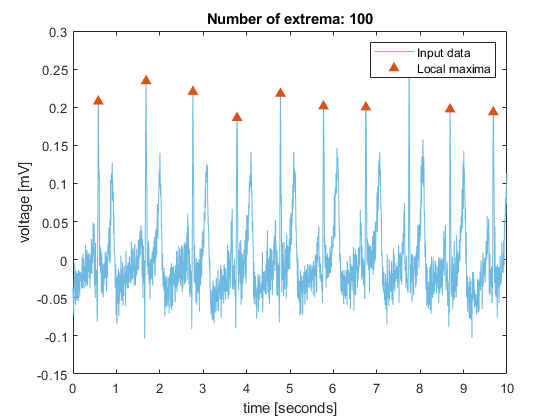

% Find local maxima
ismax = islocalmax(detrendedData,'MinProminence',0.2,'MinSeparation',0.4,...
    'MaxNumExtrema',27000,'SamplePoints',t);

% Display results
clf
plot(t,detrendedData,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(t(ismax),detrendedData(ismax),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(ismax))])
hold off
legend

xlim([0 10])
xlabel('time [seconds]')
ylabel('voltage [mV]')

## Calculate Heart Rate

We can use the detected maxima to calculate the heart rate

- Find indices of local maxima

maxIndices = find(ismax);

- calculate average time difference between two local maxima (R peaks)

sPerBeat = mean(diff(t(maxIndices)));

- calculate beats per minute

heartRate = 60/sPerBeat;
disp(['The heart rate calculated from the ECG is: ' num2str(round(heartRate)) ' bpm'])

The heart rate calculated from the ECG is: 55 bpm


# Label QRS complexes

## Creating labels with the signalLabeler

In order to evaluate our ECG signal, let's now label the signals with the signalLabeler App

subData = smoothedData(1:10000);
signalLabeler

Labeling signals manually is very time consuming, the auto-label function brings us up to speed

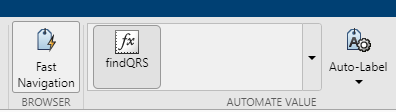

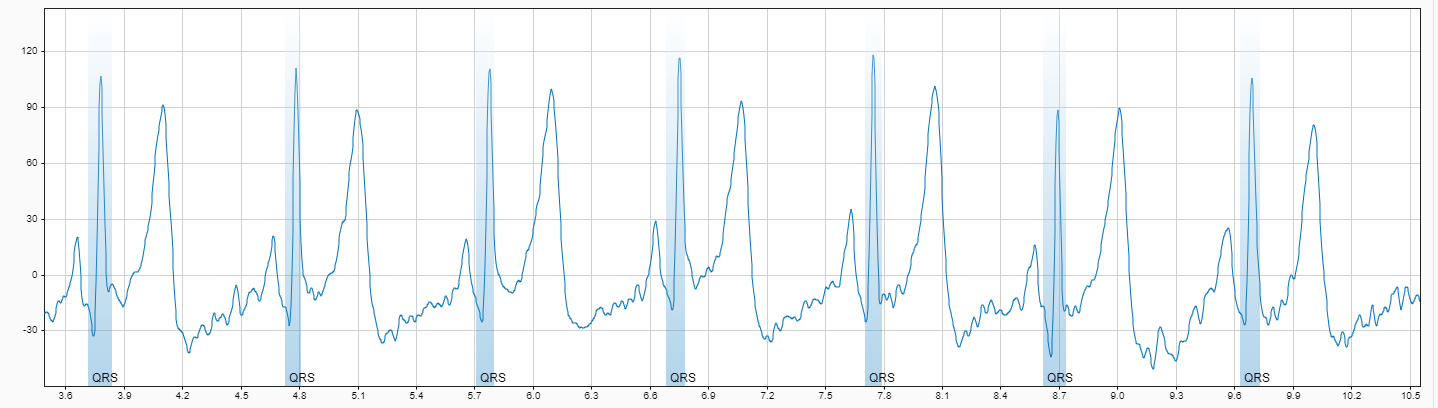

With the interactive signal labeler app we can now:

- adjust signal labels

- add signal labels

- remove false signal labels

- export the labels to the MATLAB workspace

## Autolabel data with simple deep learning approach

We use a simple deep learning approach to detect the QRS complexes 

load('trainedQTSegmentationNetwork','net');

Let's inspect the pretrained network

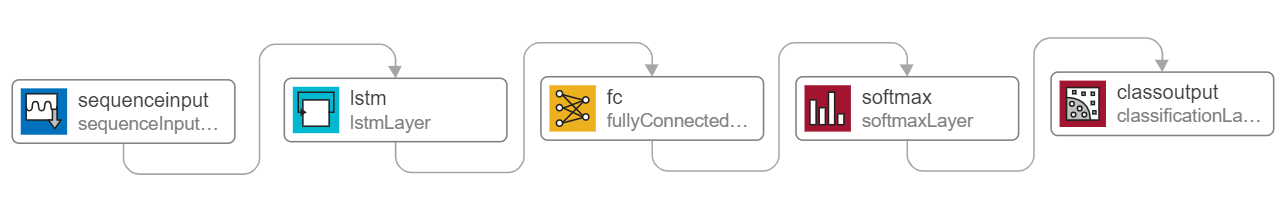

deepNetworkDesigner(net);

### Analyze data programmatically

Let's now label the other data as well.

The findQRST function will label P-waves, QRS complexes and T-Waves.

PQRSTLabels = findPQRST(subData,t(1:10000));

### Visualize labeled P-waves,QRS complexes and T-waves with signal mask

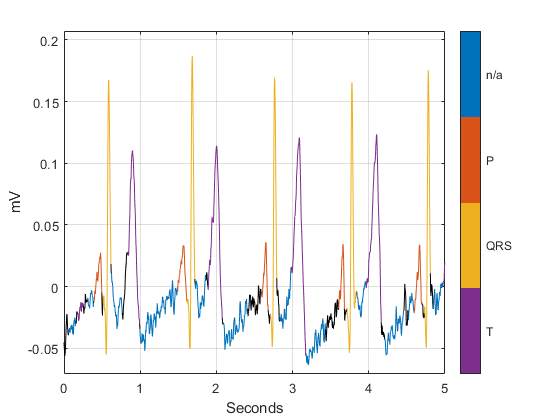

s = signalMask(PQRSTLabels,"SampleRate",250);
plotsigroi(s,subData)
xlim([0 5])
ylabel('mV')

Copyright 2020 The Mathworks, Inc.

correspondence: plaserst@mathworks.com